close all;
clear; clc;
format compact;

links = [5; 5; 5; 5];
initalState = deg2rad([60; -120; 120; -120]);
robot = SerialLinkManipulator(links, initalState);

configuration = [pi/2, -pi/4, pi/4, -pi/4]';

% fv = robot.serialLinkPoly(cspace)
% 
% figure;
% 
% p = patch (fv);
% p.FaceColor = 'red';
% p.EdgeColor = 'none';
% 
% sz = 30;
% axis equal; grid on;
% axis (sz*[-1 1 -1 1]);

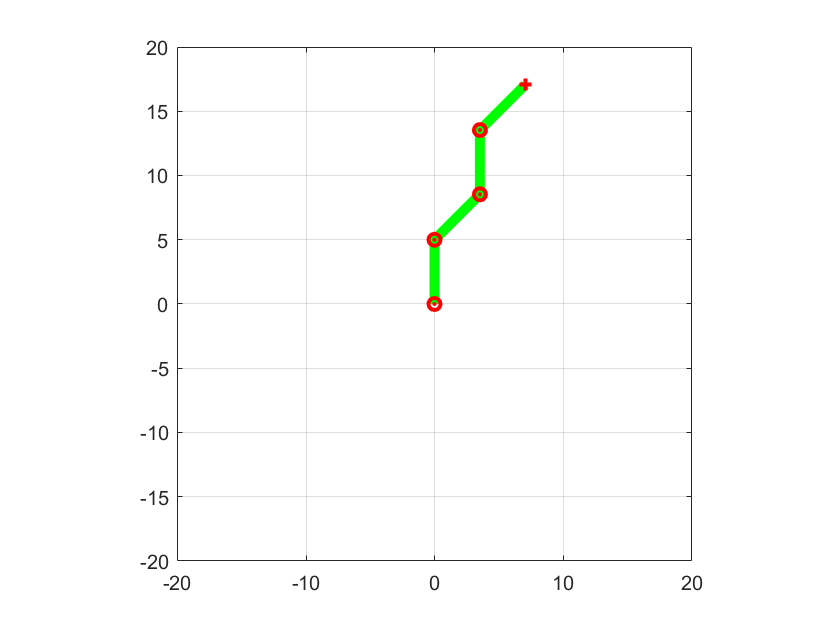

plotSize = 20;
joints = robot.taskSpace(configuration, plotSize);

% pos = [];
% for i = -pi/4:0.05:pi/4+0.1
%     pos = [pos, [pi/2 - i/2; -pi/4 + i/2; pi/4 + i; i]];
% end

% robot.drawConfiguration(pos);

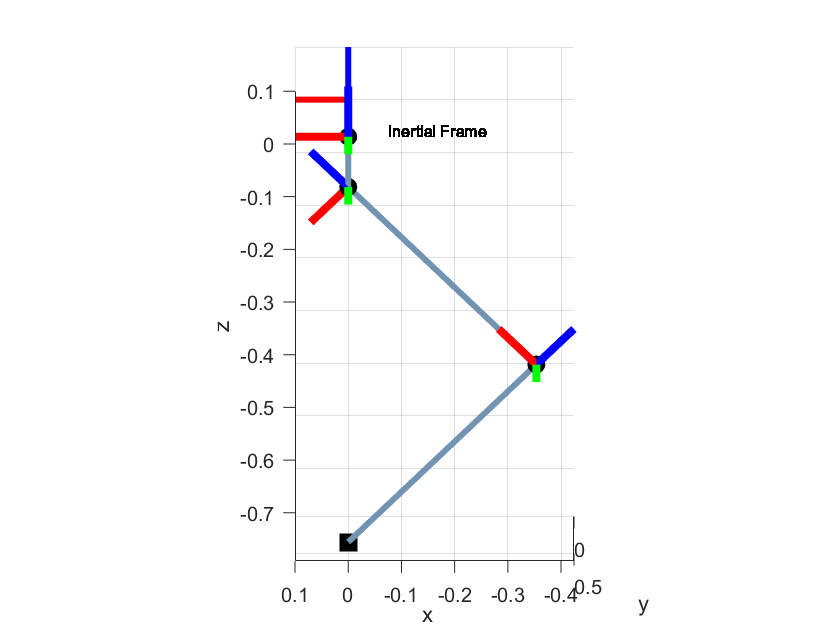

% figure;
% plots = [];
% for i = pos
%     joints = robot.taskSpace(i, false);
% 
%     plot1 = plot(   joints(:, 1), joints(:, 2), ...
%             "LineWidth", 5, "LineStyle", '-', "Color", 'g'  );
%     hold on;
%     plot2 = plot(   joints(1:robot.nJoints, 1), joints(1:robot.nJoints, 2), ...
%             'or', "LineWidth", 2);
%     hold on;
%     plot3 = plot(   joints(end, 1), joints(end, 2), ...
%             '+r', "LineWidth", 2);
%     axis equal; grid on; axis (20*[-1 1 -1 1]);
% 
%     plots = [plot1 plot2 plot3];
%     pause(0.01);
%     delete(plots);
% end